# Wavetable Oversampling Demo

### Import Wavefrom

a_Generate = true;    % Unchecked->(loads from wavebank) Checked->(generates waveforms)
a_WaveSel = 'sawtooth';
N = 256;  % Wave size (number of samples)
wave = zeros(N,1);

Loading a wavebank (00: SINE, 07: TRIANGLE, 56: SAWTOOTH, 63: SQUARE)

if (~a_Generate)
    [waves, ~] = audioread("BASIC_WA.WAV");
    switch a_WaveSel
        case 'sine'
            wave = waves(1:N);
        case 'triangle'
            wave = waves(1+N*7:N*8);
        case 'sawtooth'
            wave = waves(1+N*56:N*57);
        case 'square'
            wave = waves(1+N*63:N*64);
    end
    clear waves;
end

Generate waves

if (a_Generate)
    step = 2 * pi / N;
    phase = 0;
    for n = 1:N
        switch a_WaveSel
            case 'sine'
                wave(n) = sin(phase);
            case 'triangle'
                wave(n) = sawtooth(phase + pi/2,0.5);
            case 'sawtooth'
                wave(n) = sawtooth(phase + pi);
            case 'square'
                wave(n) = square(phase);                
        end
        phase = phase + step;
    end
end
clear step phase n;

## Oversample Wave

fs = 48000;         % sampling frequency (Hz)
f = 406.25;          % playback fundamental frequency (Hz)
ovr_smpl = 2;   % oversampling multiple
dur = 1;        % output duration (s)
a_interp = "linear";   % Interpolation method

fs_ = fs * ovr_smpl;               % oversampling frequency
p = N*f/fs_;                        % phase increment
NOut = ceil(dur * fs_);            % number of output samples
out = zeros(NOut,1);               % output

Simulate wavetable oscilattor

phase = 0;      % running phase
for n = 1:NOut
    if phase >= N
        phase = phase - N;
    end
    % Interpolate
    switch a_interp
        case 'linear'
            out(n) = linInterp(phase, wave, N);
        case 'cubic'
            out(n) = cubInterp(phase, wave, N);
        case 'hermite'
            out(n) = hermInterp(phase, wave, N);
    end
    phase = phase + p;
end
clear phase n

Display oversampled wave

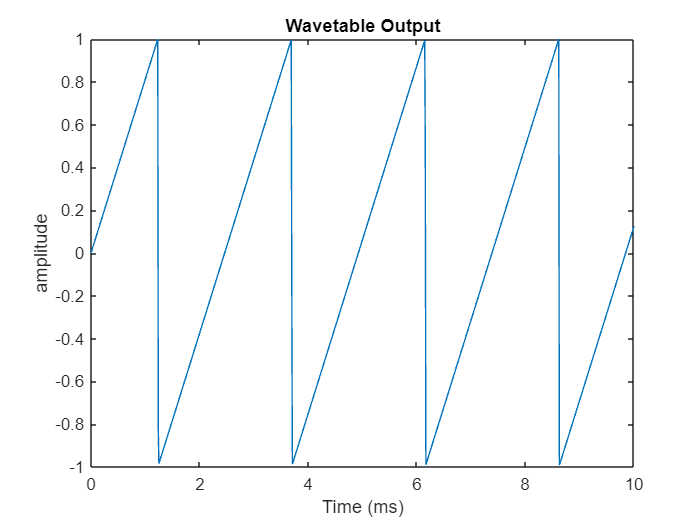

t = (0:NOut-1)/fs_;

figure
% Create plot of out
plot(1000*t,out);

xlim([0,10]);
% Add ylabel, title, and legend
xlabel("Time (ms)")
ylabel("amplitude")
title("Wavetable Output")

## FIR Lowpass Filter (anti-aliasing)

firOrder = 256;    % FIR lowpass filter order (one less than filter length)
cutoff = fs / 2;                    % cutoff frequency

b = fir1(firOrder, cutoff*2/fs_);
firCoefffs = fliplr(b);             % filter coefficients to define for CMSIS-SDP lib

Lowpass filter characteristics

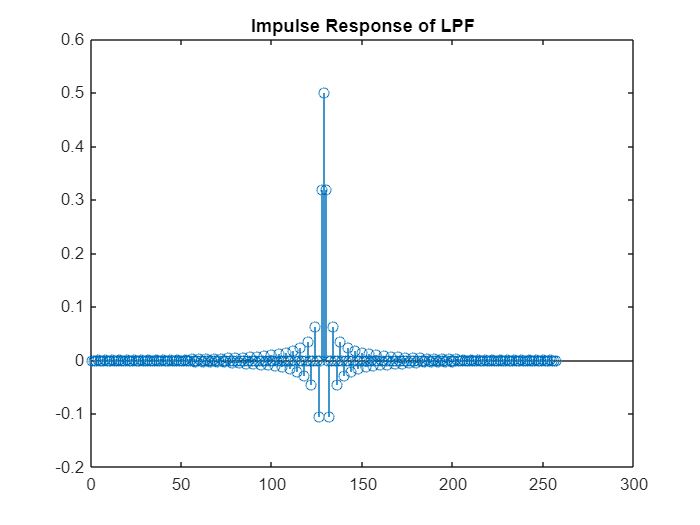

figure
stem(b)
title('Impulse Response of LPF')

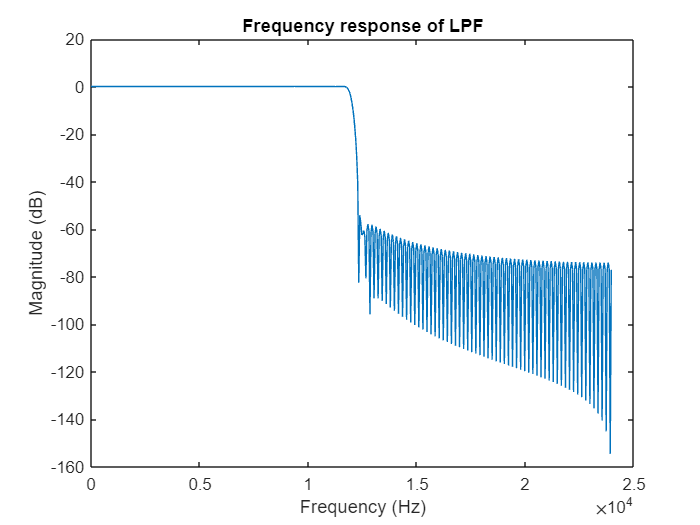


figure
[h,f] = freqz(b,1,512,fs);
plot(f,20*log10(abs(h)))
title('Frequency response of LPF')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')

Pass oversampled wave through FIR Lowpass filter

a_filter = false;  % Unchecked->(no lpf) Checked->(lpf wave)
if (a_filter)
    out = filter(b,1,out);
end

Display filtered wave

figure
% Create plot of out
plot(1000*t,out);

xlim([0,10]);
% Add ylabel, title, and legend
xlabel("Time (ms)")
ylabel("amplitude")
title("Wavetable Output")

clear t

## Downsample

out = resample(out, fs, fs_);
soundsc(out, fs)

## FFT Analyse Output

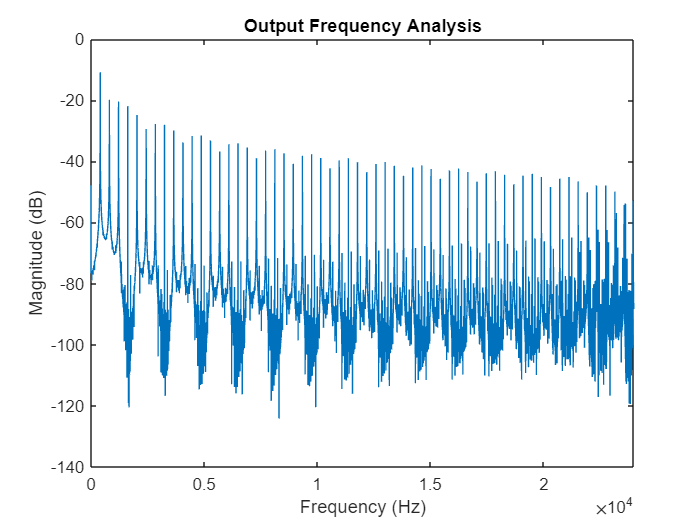

NOut = NOut / ovr_smpl;
w = window(@hamming,length(NOut));
y = fft(w.*out);
mag = db(y/NOut);
mag = mag(1:NOut/2+1);
amp = abs(y/NOut);
amp = amp(1:NOut/2+1);
amp(2:end-1) = 2*amp(2:end-1);
freq = fs*(0:NOut/2)/NOut;

figure
plot(freq, mag)

xlim([0,fs/2]);
title('Output Frequency Analysis')
ylabel('Magnitude (dB)')
xlabel('Frequency (Hz)')